licz=[10 10];
mian=[0.001 0.05 0.3 -1 1];

G=tf(licz,mian)

G =
 
                10 s + 10
  --------------------------------------
  0.001 s^4 + 0.05 s^3 + 0.3 s^2 - s + 1
 
Continuous-time transfer function.
Model Properties


Gz=G/(1+G)

Gz =
 
                         0.01 s^5 + 0.51 s^4 + 3.5 s^3 - 7 s^2 + 10
  ----------------------------------------------------------------------------------------
  1e-06 s^8 + 0.0001 s^7 + 0.0031 s^6 + 0.038 s^5 + 0.502 s^4 + 3 s^3 - 5.4 s^2 - 2 s + 11
 
Continuous-time transfer function.
Model Properties



plotoptions=''


plotoptions =

  0×0 empty char array



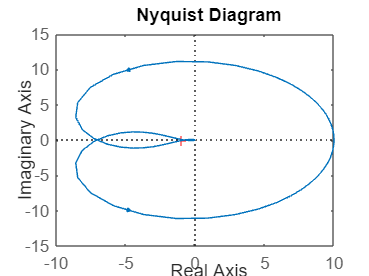

%plotoptions=nyquistoptions('cstprefs')
%plotoptions.ShowFullContour='off'
nyquist(G,plotoptions)

p=pole(G)

p =  -42.3443 + 0.0000i
 -10.2412 + 0.0000i
   1.2928 + 0.7966i
   1.2928 - 0.7966i


licz1=[1];
mian1=[1 1];
G1=tf(licz1,mian1)

G1 =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


h=nyquist(G1);


[r, theta] = cart2pol(h);

Not enough input arguments.

Error in cart2pol (line 23)
th = atan2(y,x);

theta_deg = rad2deg(theta);

polarplot(theta,r)

% Trajektoria punktu na płaszczyźnie zespolonej (przykładowe dane)
trajectory = [0.5 + 0.5i, -0.5 + 0.5i, -0.5 - 0.5i, 0.5 - 0.5i]; % Przykładowa trajektoria

% Oblicz różnicę fazową między kolejnymi punktami
phase_diff = diff(angle(h));

% Oblicz liczbę okrążeń punktu na płaszczyźnie zespolonej
num_circuits = sum(phase_diff < 0);

% Wynik
disp(['Liczba okrążeń punktu na płaszczyźnie zespolonej: ', num2str(num_circuits)]);

Liczba okrążeń punktu na płaszczyźnie zespolonej: 0
